# BouncingBallDrag

Models a bouncing ball that includes drag and examines effect of drag on effective coefficient of restitution. It uses ode45 with event location to terminate each flight at a bounce. After each bounce, the simulation restarts with post bounce initial conditions in which the velocity is reversed with a coefficient of restitution applied. This code is modelled after the MATHWORKs demo `ballode. `Uses SI units throughout.

Author: D. Carlsmith

### Initialize

Clear workspace and figures.

clear;delete(findall(0,'Type','figure'))

Define global variables to pass to function defining equation of motion.

global g alpha;

Acceleration of gravity.

g=9.81;

Compute drag coefficient for ping pong ball. 

m=0.0027;       %ball mass
d=0.040;        %ball diameter
A=(1/4)*pi*d^2; %ball area
Cd=0.4;         %ball drag coefficient (neglecting velocity dependence)
rho=1.225;      %density of air at room temperature and sealevel
alpha=(1/2)*Cd*A/m

alpha = 0.0931

%alpha=.1;

Set coefficient of restitution.

COR=.96;

Set start and end times for ode45. 

tstart = 0;
tfinal = 60;

Set initial position and upwards velocity. 

y0 = [1; 0];% drop from rest at 1 m height

Set options for ode45 to catch y=0 crossing events, output the results, and use higher than default density of points when plotting.

refine=10;
options = odeset('Events',@events,'OutputFcn',@odeplot,'OutputSel',1,...
   'Refine',refine);

Create figure for odeplot.

fig = figure;
hold on;
tout = tstart;
yout = y0.';

Initialize, as empty, arrays to hold bounce times.

teout = [];
yeout = [];
ieout = [];

### Loop over bounces.

nbounce=35;
for i = 1:nbounce   

Solve equation of motion until the first terminal event.

   [t,y,te,ye,ie] = ode45(@f,[tstart tfinal],y0,options);  

Accumulate motion output without repeating the bounce event time.  

   nt = length(t);
   tout = [tout; t(2:nt)];
   yout = [yout; y(2:nt,:)];   

Accumlate bounce events. Events at tstart are never reported.

   teout = [teout; te];          
   yeout = [yeout; ye];
   ieout = [ieout; ie];

Set the new initial conditions to reverse velocity but decreases speed by the COR.

   y0(1) = 0;   
   y0(2) = -COR*y(nt,2);

   A good guess of a valid first timestep is the length of the last valid  timestep, so use it for faster computation.  

   options = odeset(options,'InitialStep',t(nt)-t(nt-refine),...
      'MaxStep',t(nt)-t(1));
   tstart = t(nt);
end

Plot ball height versus time and the bounce event locations.

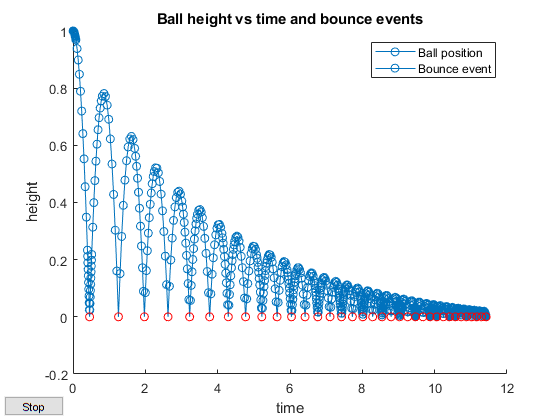

plot(teout,yeout(:,1),'ro')
xlabel('time');ylabel('height');
title('Ball height vs time and bounce events');
legend('Ball position','Bounce event')
hold off

Plot bounce times.

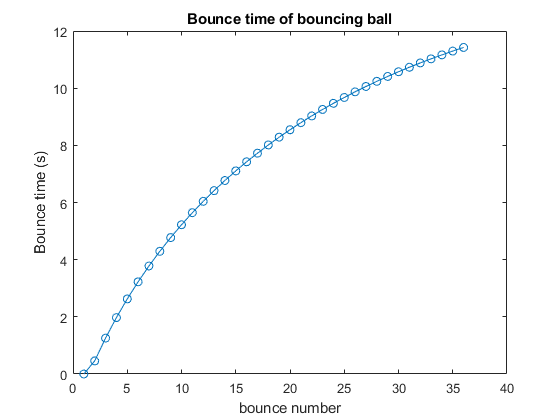

tout=[0;teout];
figure
plot(tout,'o-')
title('Bounce time of bouncing ball')
xlabel('bounce number');ylabel('Bounce time (s)')

In the absence of drag, the flight time between bounces is $2v/g$ with $v$ the initial and final speed so a COR reducing the velocity by a constant fraction reduces the flight time by a constant fraction.

Compute ratios of sucessive flight times to estimate effective COR. 

tdiff=diff(tout);
tdiffratio=tdiff(2:end)./tdiff(1:end-1);

If the initial condition is not a launch from y=0, drop the first bounce which has ~half the flight time.

if y0(1)==0
    tdiffratio=tdiffratio(2:end);
end

Plot effective coefficient of restitution.

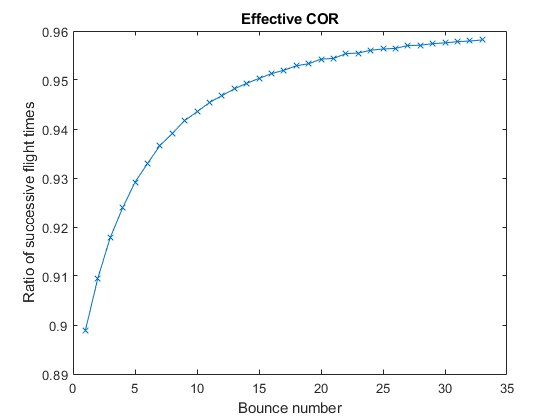

plot(tdiffratio,'x-')
xlabel('Bounce number');ylabel('Ratio of successive flight times')
title('Effective COR') 

Plot effective coefficient of restitution versus bounce time interval (proportional to bounce velocity and bounce height).

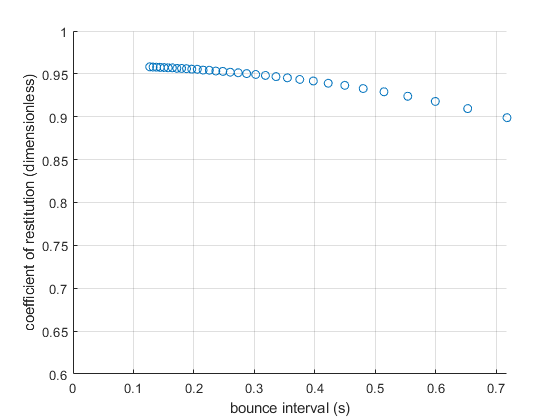

scatter(tdiff(3:end),tdiffratio)
xlabel('bounce interval (s)');ylabel('coefficient of restitution (dimensionless)')
xlim([0.0,min(1.0,max(tdiff(3:end)))]);ylim([0.6,1])
grid on

Function describing the dynamics of freefall with drag proportional to the square of speed, $\ddot y=-g-\alpha \dot y |\dot y |$.

function y_t = f(t,y)
global g alpha

$\dot y = y(2)=v_y$; $\dot v_y=-g-\alpha v_y|v_y|$

y_t = [y(2); -g-alpha*y(2)*abs(y(2))];
end

Function to terminate free fall when $y(t)=0$.

function [value,isterminal,direction] = events(t,y)

Locate the time when height passes through zero in a decreasing direction and stop integration.

value = y(1);     % detect height = 0
isterminal = 1;   % stop the integration
direction = -1;   % negative direction
end